clc
clear all
close all
%webcamlist
%preview(cam)
% Create the face detector object.This is the frontal face LBP
%read at : https://in.mathworks.com/help/vision/ref/vision.cascadeobjectdetector-system-object.html#bs_kj0p
%
faceDetector = vision.CascadeObjectDetector('UpperBody');
% Create the point tracker object.
pointTracker = vision.PointTracker('MaxBidirectionalError', 2);
% Capture one frame to get its size.
cam = webcam;
videoFrame = snapshot(cam)

videoFrame = 480×640×3 uint8 array
videoFrame(:,:,1) =

    24    27    27    24    23    23    25    27    28    29    30    31    32    32    34    33    34    33    33    32    32    32    31    31    31    30    30    30    29    29    28    26    24    23    21    19    17    15    15    14    14    15    15    15    15    15    14    12    12    14    16    17    16    16    14    14    14    16    17    17    19    19    17    17    17    19    20    21    20    20    20    20    19    19    19    17    17    17    19    19    16    17    17    18    19    18    17    17    16    16    17    17    17    17    17    18    18    19    21    21    19    18    15    17    19    20    20    20    20    20    19    19    20    20    20    20    20    20    22    23    25    26    26    26    28    26    26    26    26    25    24    25    26    28    29    31    29    29    28    28    28    28    28    27    25    24    25    27    28    28    27    29    27    26    25    25    23  

frameSize = size(videoFrame)

frameSize =    480   640     3


% Create the video player object.
videoPlayer = vision.VideoPlayer('Position', [100 100 [frameSize(2), frameSize(1)]+30])

videoPlayer =   vision.VideoPlayer with properties:

        Name: 'Video Player'
    Position: [100 100 670 510]


**create the database.**

cam =   webcam with properties:

                     Name: 'USB2.0 VGA UVC WebCam'
     AvailableResolutions: {'640x480'  '160x120'  '176x144'  '320x240'  '352x288'}
               Resolution: '640x480'
         WhiteBalanceMode: 'auto'
                 Exposure: -6
                 Contrast: 50
               Brightness: 0
                    Gamma: 300
             ExposureMode: 'auto'
               Saturation: 50
                      Hue: 0
             WhiteBalance: 4600
    BacklightCompensation: 0
                Sharpness: 50


cam =   webcam with properties:

                     Name: 'USB2.0 VGA UVC WebCam'
     AvailableResolutions: {'640x480'  '160x120'  '176x144'  '320x240'  '352x288'}
               Resolution: '640x480'
                Sharpness: 50
                      Hue: 0
                    Gamma: 300
         WhiteBalanceMode: 'auto'
               Saturation: 50
             WhiteBalance: 4600
               Brightness: 0
             ExposureMode: 'auto'
    BacklightCompensation: 0
                 Exposure: -6
                 Contrast: 50


cam =   webcam with properties:

                     Name: 'USB2.0 VGA UVC WebCam'
     AvailableResolutions: {'640x480'  '160x120'  '176x144'  '320x240'  '352x288'}
               Resolution: '640x480'
               Saturation: 50
                      Hue: 0
                Sharpness: 50
             WhiteBalance: 4600
    BacklightCompensation: 0
                 Exposure: -6
             ExposureMode: 'auto'
               Brightness: 0
                    Gamma: 300
         WhiteBalanceMode: 'auto'
                 Contrast: 50


cam =   webcam with properties:

                     Name: 'USB2.0 VGA UVC WebCam'
     AvailableResolutions: {'640x480'  '160x120'  '176x144'  '320x240'  '352x288'}
               Resolution: '640x480'
         WhiteBalanceMode: 'auto'
                    Gamma: 300
    BacklightCompensation: 0
               Saturation: 50
             ExposureMode: 'auto'
                 Exposure: -6
                      Hue: 0
                 Contrast: 50
               Brightness: 0
             WhiteBalance: 4600
                Sharpness: 50


cam =   webcam with properties:

                     Name: 'USB2.0 VGA UVC WebCam'
     AvailableResolutions: {'640x480'  '160x120'  '176x144'  '320x240'  '352x288'}
               Resolution: '640x480'
                 Contrast: 50
                    Gamma: 300
                 Exposure: -6
    BacklightCompensation: 0
         WhiteBalanceMode: 'auto'
                Sharpness: 50
                      Hue: 0
             ExposureMode: 'auto'
               Brightness: 0
             WhiteBalance: 4600
               Saturation: 50


cam =   webcam with properties:

                     Name: 'USB2.0 VGA UVC WebCam'
     AvailableResolutions: {'640x480'  '160x120'  '176x144'  '320x240'  '352x288'}
               Resolution: '640x480'
                      Hue: 0
         WhiteBalanceMode: 'auto'
                Sharpness: 50
             WhiteBalance: 4600
    BacklightCompensation: 0
                    Gamma: 300
             ExposureMode: 'auto'
                 Contrast: 50
               Saturation: 50
                 Exposure: -6
               Brightness: 0


cam =   webcam with properties:

                     Name: 'USB2.0 VGA UVC WebCam'
     AvailableResolutions: {'640x480'  '160x120'  '176x144'  '320x240'  '352x288'}
               Resolution: '640x480'
                    Gamma: 300
                 Contrast: 50
                Sharpness: 50
               Saturation: 50
         WhiteBalanceMode: 'auto'
             ExposureMode: 'auto'
    BacklightCompensation: 0
                      Hue: 0
               Brightness: 0
             WhiteBalance: 4600
                 Exposure: -6


cam =   webcam with properties:

                     Name: 'USB2.0 VGA UVC WebCam'
     AvailableResolutions: {'640x480'  '160x120'  '176x144'  '320x240'  '352x288'}
               Resolution: '640x480'
                 Exposure: -6
             WhiteBalance: 4600
               Saturation: 50
                Sharpness: 50
         WhiteBalanceMode: 'auto'
    BacklightCompensation: 0
             ExposureMode: 'auto'
                      Hue: 0
               Brightness: 0
                    Gamma: 300
                 Contrast: 50


cam =   webcam with properties:

                     Name: 'USB2.0 VGA UVC WebCam'
     AvailableResolutions: {'640x480'  '160x120'  '176x144'  '320x240'  '352x288'}
               Resolution: '640x480'
                    Gamma: 300
                 Exposure: -6
                      Hue: 0
                 Contrast: 50
    BacklightCompensation: 0
               Brightness: 0
               Saturation: 50
         WhiteBalanceMode: 'auto'
             WhiteBalance: 4600
             ExposureMode: 'auto'
                Sharpness: 50


cam =   webcam with properties:

                     Name: 'USB2.0 VGA UVC WebCam'
     AvailableResolutions: {'640x480'  '160x120'  '176x144'  '320x240'  '352x288'}
               Resolution: '640x480'
               Saturation: 50
                    Gamma: 300
         WhiteBalanceMode: 'auto'
             ExposureMode: 'auto'
               Brightness: 0
                 Contrast: 50
             WhiteBalance: 4600
                      Hue: 0
                 Exposure: -6
                Sharpness: 50
    BacklightCompensation: 0


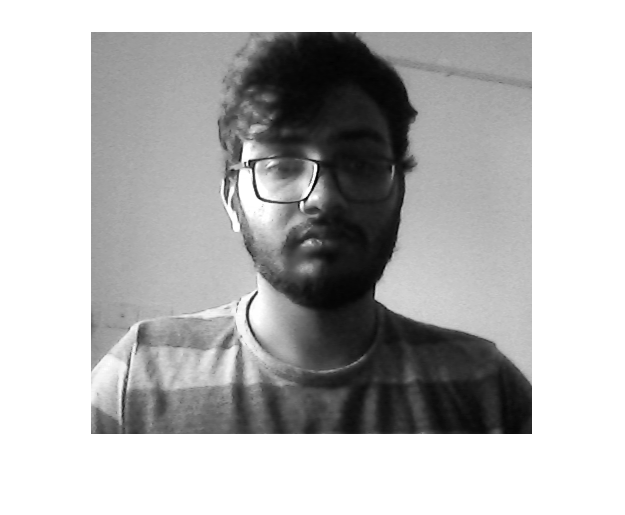

cam =   webcam with properties:

                     Name: 'USB2.0 VGA UVC WebCam'
     AvailableResolutions: {'640x480'  '160x120'  '176x144'  '320x240'  '352x288'}
               Resolution: '640x480'
                 Exposure: -6
                 Contrast: 50
    BacklightCompensation: 0
             ExposureMode: 'auto'
               Brightness: 0
             WhiteBalance: 4600
                    Gamma: 300
               Saturation: 50
                Sharpness: 50
                      Hue: 0
         WhiteBalanceMode: 'auto'


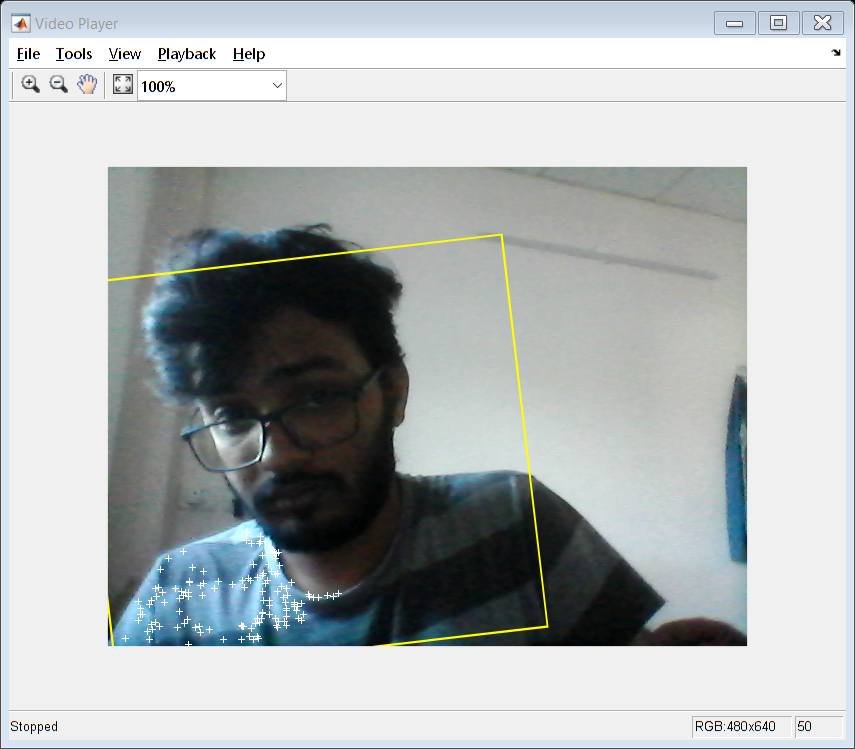

Index in position 1 exceeds array bounds (must not exceed 480).


for j = 62:72
    cam = webcam
    runLoop = true;
    numPts = 0;
    frameCount = 0;
    while runLoop && frameCount < 50
         % Get the next frame.
        videoFrame = snapshot(cam);
        
        % Get frame to save data to database
        videoFrameGray = rgb2gray(videoFrame);
        frameCount = frameCount + 1;
        
        if numPts < 100
            % Detection mode.
            bbox = faceDetector.step(videoFrameGray);
            if ~isempty(bbox)
                % Find corner points inside the detected region.
                points = detectMinEigenFeatures(videoFrameGray, 'ROI', bbox(1, :));
                
                % Re-initialize the point tracker.
                xyPoints = points.Location;
                numPts = size(xyPoints,1);
                release(pointTracker);
                initialize(pointTracker, xyPoints, videoFrameGray);
                
                % Save a copy of the points.
                oldPoints = xyPoints;
                
                % Convert the rectangle represented as [x, y, w, h] into an
                % M-by-2 matrix of [x,y] coordinates of the four corners. This
                % is needed to be able to transform the bounding box to display
                % the orientation of the face.
                bboxPoints = bbox2points(bbox(1, :));
                
                % Convert the box corners into the [x1 y1 x2 y2 x3 y3 x4 y4]
                % format required by insertShape.
                bboxPolygon = reshape(bboxPoints', 1, []);
                
                % Display a bounding box around the detected face.
                videoFrame = insertShape(videoFrame, 'Polygon', bboxPolygon, 'LineWidth', 3);
                
                % Display detected corners.
                videoFrame = insertMarker(videoFrame, xyPoints, '+', 'Color', 'blue');
            end
            
      else
            % Tracking mode.
            [xyPoints, isFound] = step(pointTracker, videoFrameGray);
            visiblePoints = xyPoints(isFound, :);
            oldInliers = oldPoints(isFound, :);
            numPts = size(visiblePoints, 1);
            if numPts >= 100
                % Estimate the geometric transformation between the old points
                % and the new points.
                [xform, oldInliers, visiblePoints] = estimateGeometricTransform(...
                    oldInliers, visiblePoints, 'similarity', 'MaxDistance', 4);
                % Apply the transformation to the bounding box.
                bboxPoints = transformPointsForward(xform, bboxPoints);
                % Convert the box corners into the [x1 y1 x2 y2 x3 y3 x4 y4]
                % format required by insertShape.
                bboxPolygon = reshape(bboxPoints', 1, []);
                
                % Display a bounding box around the face being tracked.
                videoFrame = insertShape(videoFrame, 'Polygon', bboxPolygon, 'LineWidth', 3);
                % Display tracked points.
                videoFrame = insertMarker(videoFrame, visiblePoints, '+', 'Color', 'white');
                % Reset the points.
                oldPoints = visiblePoints;
                setPoints(pointTracker, oldPoints);
            end
        end
        
          % Display the annotated video frame using the video player object.
        step(videoPlayer, videoFrame);
        % Check whether the video player window has been closed.
        runLoop = isOpen(videoPlayer);
    end
    % Clean up.
    clear cam;
    release(videoPlayer);
    release(pointTracker);
    release(faceDetector);
    
    % saving the image to database
    position1 = min(bboxPolygon(2),bboxPolygon(4));
    position2 = max(bboxPolygon(6),bboxPolygon(8));
    position3 = min(bboxPolygon(1),bboxPolygon(7));
    position4 = max(bboxPolygon(3),bboxPolygon(5));
    warning('off')
    getimage = videoFrameGray(position1:position2,position3:position4,:);
    imshow(getimage)
    %resize image
    getimage = imresize(getimage, [300 300]);
    % Modify here. In the folder database2, label the name of ppl and put their
    % faces inside the folder.
    sprintf('image%d', j);
    imwrite(getimage,strcat('Rohit',num2str(j),'.jpg'),'jpg');
    pause(1)
end 